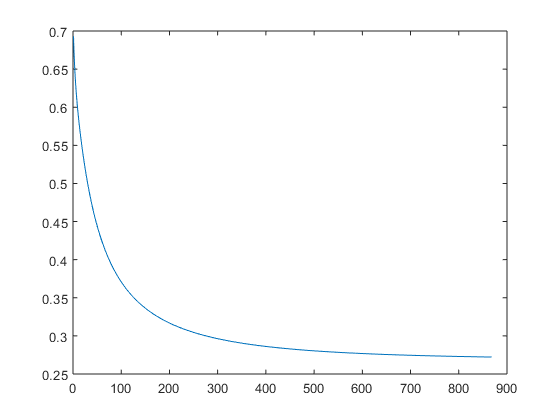

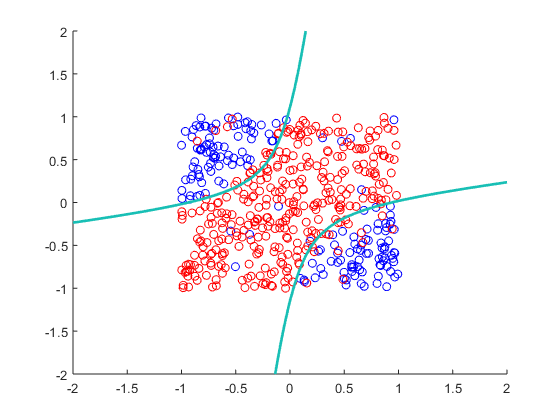

%Choose the following menu options
%menuEntry = 1  --> X1 + X2 
%menuEntry = 2  --> X1 + X2 + X1^2 + X2^2 
%menuEntry = 3  --> X1 + X2 + X1^2 + X2^2 + 3*X1*X2

menuEntry=3; %Change menu entry here

[theta accuracy] = performClassificaion('train_q1.csv',{},true,menuEntry,'grad_desc');

disp("Data training completed. Training accuracy = "+accuracy);

Data training completed. Training accuracy = 91.2


disp("Executing with test data ....");

Executing with test data ....


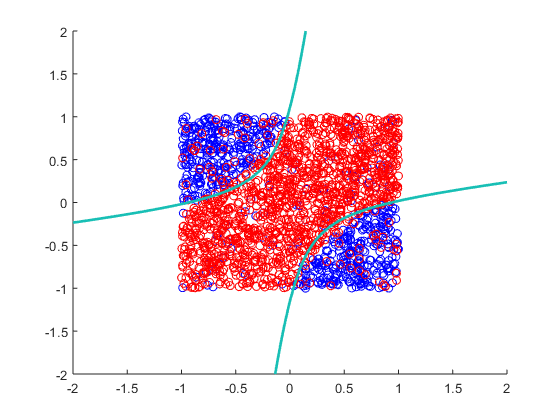

[theta accuracy] = performClassificaion('test_q1.csv',theta,false,menuEntry,'grad_desc');

disp("Accuracy on test data = "+accuracy);

Accuracy on test data = 88.35


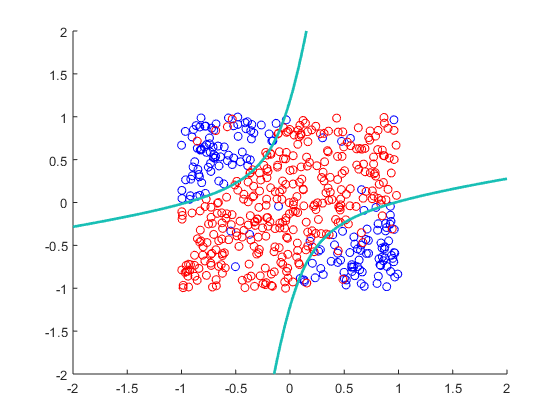




%Trying the menuEntry 3 with Newton's method
menuEntry = 3;
[theta accuracy] = performClassificaion('train_q1.csv',{},true,menuEntry,'newton_method');

disp("Data training completed. Training accuracy = "+accuracy);

Data training completed. Training accuracy = 89.8


disp("Executing with test data ....");

Executing with test data ....


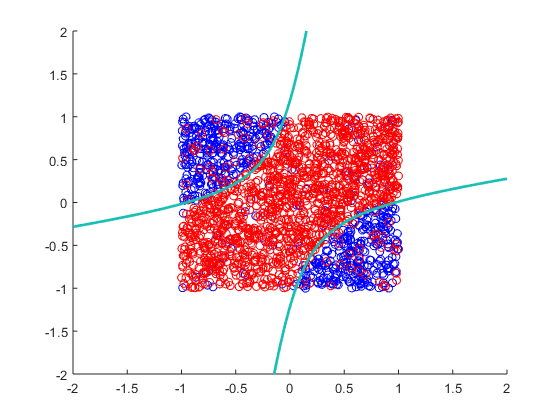

[theta accuracy] = performClassificaion('test_q1.csv',theta,false,menuEntry,'newton_method');

disp("Accuracy on test data = "+accuracy);

Accuracy on test data = 85.85


function [theta accuracy] = performClassificaion(filename,theta,isTrainingData,menuEntry,methodName)
    [X Y] = generateDataset(filename,menuEntry);
    
    if(isTrainingData) %Performs Gradient Descent only for Training Data
%         theta = perform_gradient_descent(X,Y,0.5,1000);
        if(methodName=="grad_desc")
            theta = perform_gradient_descent(X,Y,0.5,1000);
        elseif(methodName=="newton_method")
            theta = perform_newtons_method(X,Y);
        end
        figure('Name' , "Training Data Scatter Plot(" + methodName+")");
    else
        figure('Name', "Test data Scatter plot(" + methodName+")");    
    end
    
    plotScatter(X,Y)
    plotDecisionBoundary(theta,X,Y,menuEntry);
    accuracy = predictAccuracy(X,Y,theta);
end


function [X Y] = generateDataset(filename,menuEntry)
    data_train = readtable(filename);
    m = size(data_train,1);
    X = [ones(m,1) table2array(data_train(:,1:2))];
    if(menuEntry==2)
        X = [X X(:,2).^2 X(:,3).^2];
    elseif(menuEntry==3)
        X = [X X(:,2).^2 X(:,3).^2 X(:,2).*X(:,3)];
    end
    Y = table2array(data_train(:,3)) == "buy";
end

function theta_gd = perform_gradient_descent(x,y,alpha, iterations)
     
    m = size(x,1);   % Number of data records
    n = size(x,2);   % Number of features 
    
    %Assuming some random value of theta, alpha and iterations
    theta = zeros(n,1);
    
    J=zeros(iterations,1);  % Preallocating for performance
    %Beginning of the interest
    for i = 1:iterations
        h = sigmoid(x * theta);
        gradient = x' * (h-y);
        theta = theta - (alpha/m)*gradient;
        
        J(i) = (-1/m)*sum(y'*log(h) + (1-y)'*log(1-h));
        if((i>2 && abs(J(i-1) - J(i)) < 10^-5))
             J(i+1:end) = [];
             break;
        end
        
        if(any(isnan(theta())))
            disp("breaking the iterations since theta returns NaN values",'r');
            J(i+1:end) = [];
            break;
        end

    end
    figure('Name',"Gradient Descent");
    plot(1:i,J);
    theta_gd = theta;
end

function theta_gd = perform_newtons_method(x,y)
    
    m = size(x,1);   % Number of data records
    n = size(x,2);   % Number of features 
    
    %Assuming some random value of theta, alpha and iterations
    theta = zeros(n,1);
    i=1;                              
    %Beginning of the interest
    while(true)
        h = sigmoid(x * theta);
        gradient = x' * (h-y);
        hessian = ((x'*x)*(h'*(1-h)));
        theta = theta - (1/m^2)*pinv(hessian)*gradient;
        
        J(i) = (-1/m)*sum(y'*log(h) + (1-y)'*log(1-h));
        if((i>2 && abs(J(i-1) - J(i)) < 10^-5))
             J(i+1:end) = [];
             break;
        end
        
        
        i=i+1;
    end
% Not plotting anything for Newtwons method
%     figure('Name',"Gradient Descent");
%     plot(1:i,J);
    theta_gd = theta;
end

%Standard Sigmoid function 
function sig = sigmoid(X)
    sig = 1./(1 + exp(-X));
end


function plotScatter(X,Y)
    scatter(X(find(Y==1),2),X(find(Y==1),3),'b');
    hold on;
    scatter(X(find(Y==0),2),X(find(Y==0),3),'r');
    hold on;
end


% This logic is something I still have to understand. I pulled it from
% AndrewNg course on coursera for better visualization

function plotDecisionBoundary(theta, X, y, menuEntry)
    %PLOTDECISIONBOUNDARY Plots the data points X and y into a new figure with
    %the decision boundary defined by theta
    if size(X, 2) <= 3
        % Only need 2 points to define a line, so choose two endpoints
        plot_x = [min(X(:,2)),  max(X(:,2))];
    
       
        % Calculate the decision boundary line  --> y = mx + c
        plot_y = (theta(2).*plot_x + theta(1));
    
        % Plot, and adjust axes for better viewing
        plot(plot_x, plot_y)

    else
        % Here is the grid range  --> similar to meshgrid for 3D
        u = linspace(-2, 2, 50);
        v = linspace(-2, 2, 50);
        % u and v are N X 1 vectors ranging from -2 to 2 with length of 50
        z = zeros(length(u), length(v));
        % Evaluate z = theta*x over the grid
        for i = 1:length(u)
            for j = 1:length(v)
                z(i,j) = map_feature(u(i), v(j),menuEntry)*theta;
            end
        end
        z = z'; % important to transpose z before calling contour
    
        % Plot z = 0
        % Notice you need to specify the range [0, 0]
        contour(u, v, z, [0, 0], 'LineWidth', 2)
    end
    hold off
    
end





% The idea of writing this function is also picked up from Andrew Ng course
%Takes X1 and X2 as two vectors and returns a new vector with polynomial
%operations of X1 and X2
function out = map_feature(X1, X2,menuEntry)
    
    
        out = [1 X1 X2];
    if(menuEntry==2)
        out = [1 X1 X2 X1^2 X2^2];
    elseif(menuEntry==3)
        out = [1 X1 X2 X1^2 X2^2 3*X1*X2];
    end
    
    

end

function accuracy = predictAccuracy(X,Y,theta)
    accuracy = 100 * (sum((sigmoid(X*theta)>=0.5) == Y) / size(X,1));
end
